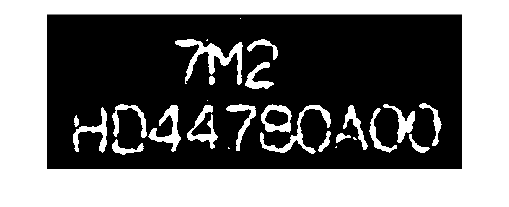

addpath('functions');  % load functions
picture = "./pictures/charact2.jpg";  % load the picture
origin_image = imread(picture);

% use previous functions to do preprocessing
image = rgb2gray(origin_image);
image = contrast(image,0.45,3);
image = average_filter(image,11);

% change it to binary image
BW = rgb2binary(image, 80);
figure, imshow(BW)

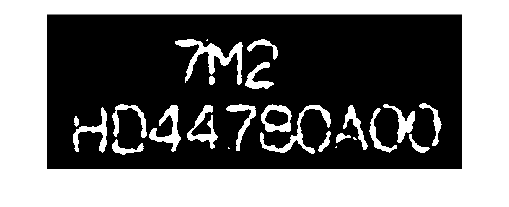

BW = white_8(BW, 4);
figure, imshow(BW)

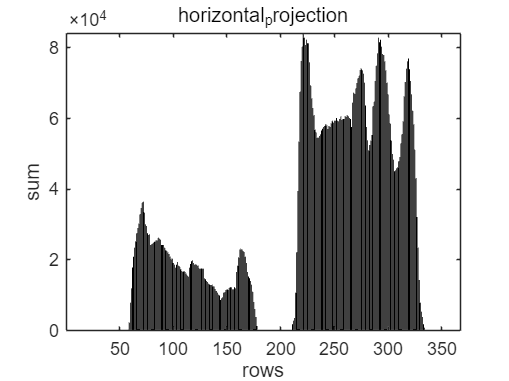


% horizontal_projection
[line_starts, line_ends] = find_text_line(BW);

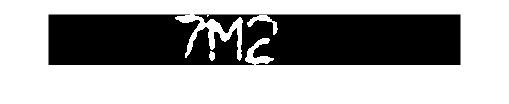

% segmentation by lines
lines = horizon_seg(BW, line_starts, line_ends);
figure, imshow(lines{1});

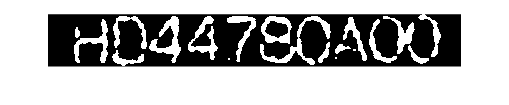

figure, imshow(lines{2});

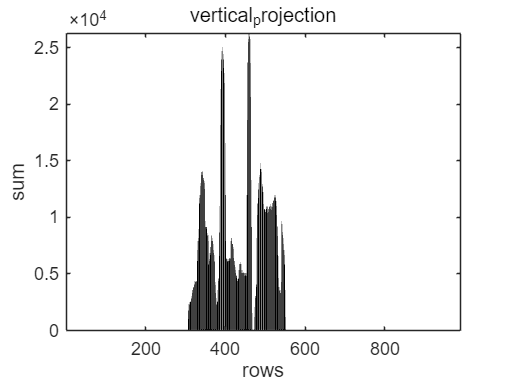

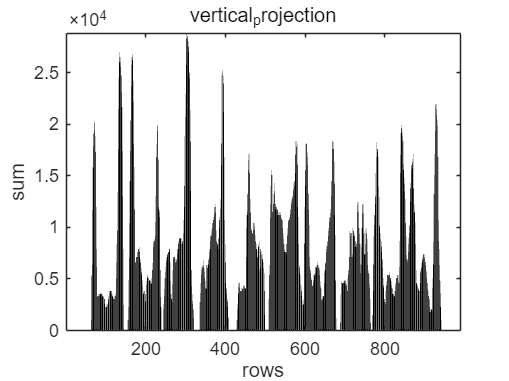

% vertical_projection
[character_starts_cell, character_ends_cell] = find_characters(lines);

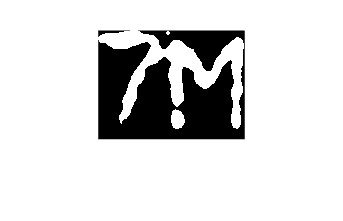

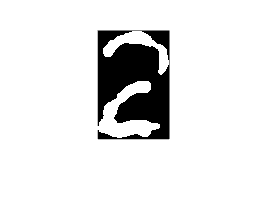

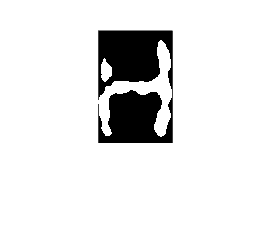

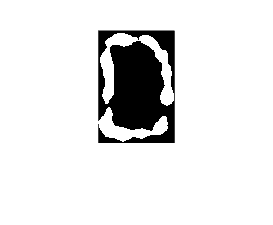

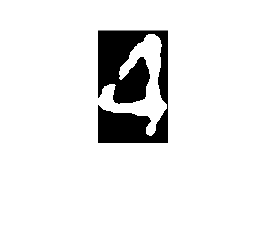

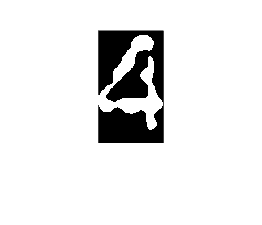

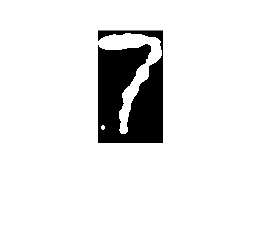

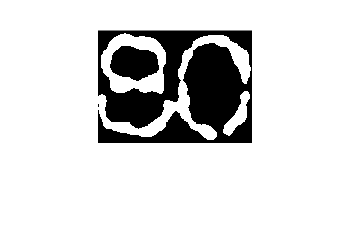

characters = vertical_seg(lines, character_starts_cell, character_ends_cell);
% show each characters
for i = 1:length(characters)
    figure, imshow(characters{i})
end